

syms ang1 ang2 ang3 L1 L2 L3

xFormula = L1*cos(ang1) + L2*cos(ang1 + ang2) + L3*cos(ang1 + ang2 + ang3);
yFormula = L1*sin(ang1) + L2*sin(ang1 + ang2) + L3*sin(ang1 + ang2 + ang3);
x_dotFormula = diff(xFormula);
y_dotFormula = diff(yFormula);

h = [x_dotFormula; y_dotFormula; 0];
J = jacobian(h, [ang1 ang2 ang3]);
J_T = transpose(J);

Analysis of the relationship between 2 optimisation metrics and the robots joints range of motions:

max) det(JJ^T)

Algebra

syms ang1 ang2 ang3 L1 L2 L3 phi real 

L1 = 1;

L1 = 1

L2 = 1;

L2 = 1

L3 = 1;

L3 = 1


phi = ang1 + ang2 + ang3;


Posx = L1*cos(ang1) + L2*cos(ang1 + ang2) + L3*cos(ang1 + ang2 + ang3);
Posy = L1*sin(ang1) + L2*sin(ang1 + ang2) + L3*sin(ang1 + ang2 + ang3);

Pwx = L1*cos(ang1) + L2*cos(ang1 + ang2);
Pwy = L1*sin(ang1) + L2*sin(ang1 + ang2);

c2 = (Pwx^2 + Pwy^2 - L1^2 - L2^2)/(2*L1*L2);

s2 = sqrt(1-c2^2);

ang2 = atan2(s2,c2);

c1 = ((L1 + L2*c2)*Pwy - L2*s2*Pwx)/(Pwx^2 + Pwy^2);
s1 = ((L1 + L2*c2)*Pwx + L2*s2*Pwy)/(Pwx^2 + Pwy^2);

ang1 = atan2(s1,c1);


ang3 = phi - ang1 - ang2;


J = [-L1*sin(ang1)-L2*sin(ang1+ang2)-L3*sin(ang1+ang2+ang3), -L2*sin(ang1+ang2)-L3*sin(ang1+ang2+ang3), -L3*sin(ang1+ang2+ang3);
    L1*cos(ang1)+L2*cos(ang1+ang2)+L3*cos(ang1+ang2+ang3), L2*cos(ang1+ang2)+L3*cos(ang1+ang2+ang3), L3*cos(ang1+ang2+ang3)];
J_T = transpose(J);


detminJ = det(J *J_T);




Numerical


L1 = 0.2817;
L2 = 0.2689;
L3 = 0.0862;

px = 0;
py = 0;
phi = 0;



%phi = ang1 + ang2 + ang3;


%Posx = L1*cos(ang1) + L2*cos(ang1 + ang2) + L3*cos(ang1 + ang2 + ang3);
%Posy = L1*sin(ang1) + L2*sin(ang1 + ang2) + L3*sin(ang1 + ang2 + ang3);

%Pwx = L1*cos(ang1) + L2*cos(ang1 + ang2);
%Pwy = L1*sin(ang1) + L2*sin(ang1 + ang2);

Pwx = px - L3*cos(phi);
Pwy = py - L3*sin(phi);

c2 = (Pwx^2 + Pwy^2 - L1^2 - L2^2)/(2*L1*L2);
if c2 > 1
    
   s2 = NaN;
   %not a number
else
    
s2 = sqrt(1-c2^2);

ang2 = atan2(s2,c2);

c1 = ((L1 + L2*c2)*Pwy - L2*s2*Pwx)/(Pwx^2 + Pwy^2);
s1 = ((L1 + L2*c2)*Pwx + L2*s2*Pwy)/(Pwx^2 + Pwy^2);

ang1 = atan2(s1,c1);


ang3 = phi - ang1 - ang2;


J = [-L1*sin(ang1)-L2*sin(ang1+ang2)-L3*sin(ang1+ang2+ang3), -L2*sin(ang1+ang2)-L3*sin(ang1+ang2+ang3), -L3*sin(ang1+ang2+ang3);
    L1*cos(ang1)+L2*cos(ang1+ang2)+L3*cos(ang1+ang2+ang3), L2*cos(ang1+ang2)+L3*cos(ang1+ang2+ang3), L3*cos(ang1+ang2+ang3)];
J_T = transpose(J);


detminJ = det(J *J_T);


    
end

detminJ = 0.0011

Changed to be function

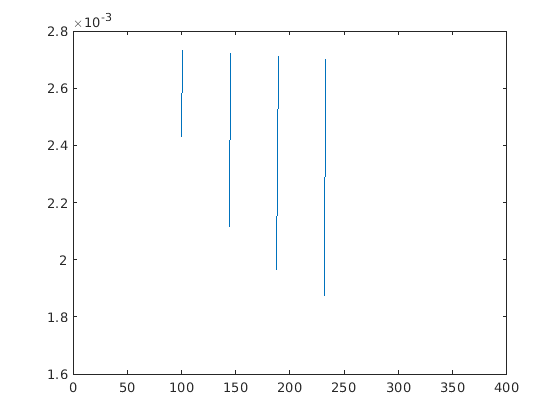


px = 0.62;
py = 0;

phi = linspace(1, 360, 360)*2*pi/360; 
detJJ = linspace(1, 360, 360)*2*pi/360; 

for i = 1:length(phi)
    
    detJJ(i) = calcDetJJ(i, px, py);
    
    
end

plot(detJJ)